# Alinea A

T = 1000;
N = 100;
keys = 10;
count = 0;

for j= 1:N
    array = zeros(1,10);
    for i = 1:keys
        arrayAdr = randi ([0 T-1]);
        array(i) = arrayAdr;
    end
    if length(array) ~= length(unique(array))
        count = count + 1;
    end
end

prob = count/N

prob = 0.0500

## Alinea B

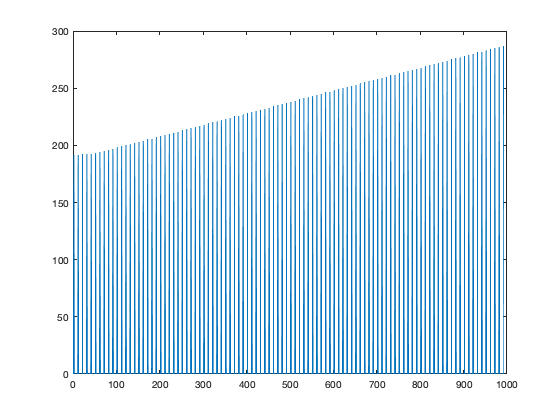

results = zeros(1,100);
T = 1000;
N = 100;
for k = 1:10:1000
    count = 0;
    for j = 1:N
        array = zeros(1,k);
        for i = 1:k
            array(i) = randi([0 T-1]);
        end 
        if length(array) ~= length(unique(array)) 
            numInter = numInter+1;
        end
    end
    results(k+10/10) = numInter/N;
end
plot(results)